# Face Detection using Skin Tone Segmentation and Facial Features

## Reading the Dataset:

clc
clear all
I=imread('4.jfif');

## Extracting Foreground from Background:

As we are segmenting the object from the background using the intensity level so this approach might fail for bad lightning conditions. We will convert the RGB image into YCbCr color space to segment the object more efficiently as this handles the daylight better than RGB color thresholds.

## Parameter Selection:

These parameters set the segmentation of image by choosing the intesity level , Ideally thes paramters should work globally for every unseen image but due to limitation of this algorithm, we had to tune the parameter only for the first image to get appropriate results.

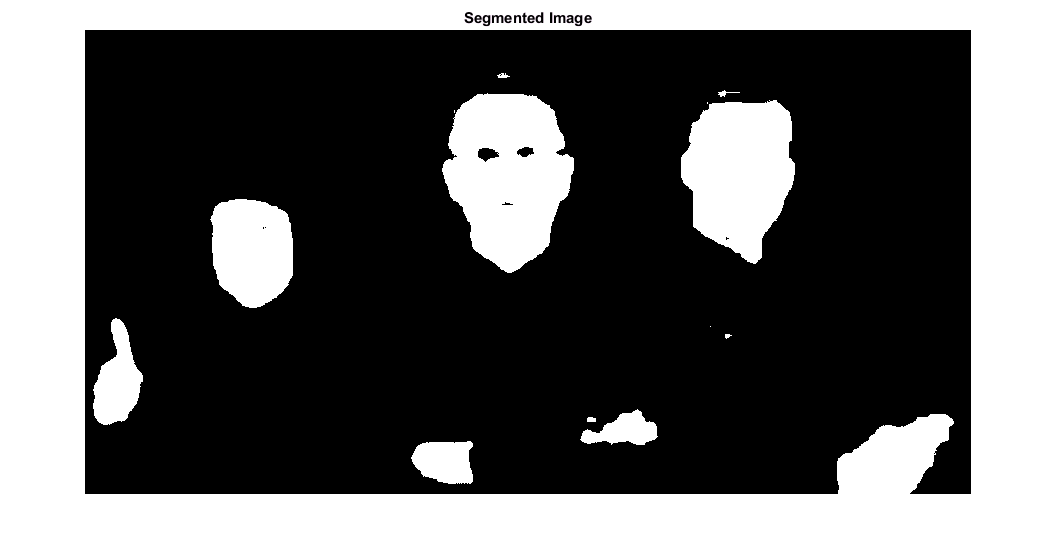

%  input: Input RGB Image,
%         lower_thresh,higher_thresh: setting of chromatic intesity
%         paramter for objects
%  Output: Segmented image
I=double(I);
lower_thresh=10;
higher_thresh=45;
H=size(I,1); % height 
W=size(I,2); % width
YCbCr=rgb2ycbcr(I); % RGB to YCbCr
Cr=YCbCr(:,:,3);
s=zeros(H,W);
[SkinIndexRow,SkinIndexCol] =find(lower_thresh<Cr & Cr<higher_thresh); % finding the co-ordinates of foreground
for i=1:length(SkinIndexRow)
    s(SkinIndexRow(i),SkinIndexCol(i))=1;
end
figure,imshow(s);
title('Segmented Image');

## Instance Detection:

In this function, we try ot find the probable objects that can be face. This step gives us a matrix of all the objects that have facial features. This function might give us some false positives like a child arm could be classified as a face if it satissfies our fixed criteria that is set after literature review and hit and trial method. 

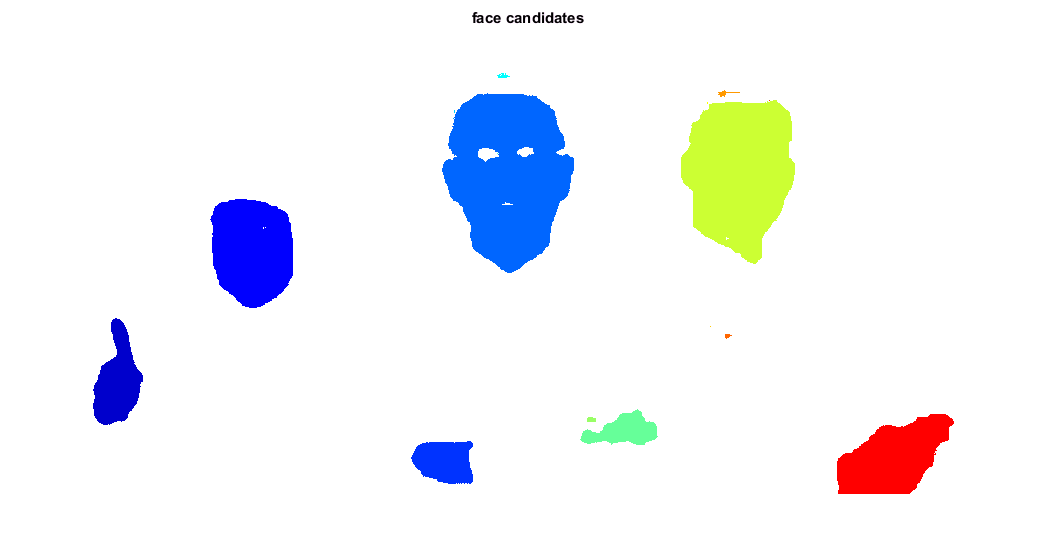

labeld = bwlabel(s,4); % labeling the binary image using 4-connectivit
BB  = regionprops(labeld, 'BoundingBox');
bboxes= cat(1, BB.BoundingBox); % bounding box
widths=bboxes(:,3);
heights=bboxes(:,4);
hByW=heights./widths; % New Feature for face detection
lenRegions=size(bboxes,1); % Total number of Faces
foundFaces=zeros(1,lenRegions);
num_faces=0;
probable_faces=label2rgb(labeld);
figure,imshow(probable_faces);
title('face candidates');

for i=1:lenRegions
    % height to width ratio, computed above.
    if (hByW(i)>1.75 || hByW(i)<0.75)
        % this cannot be a mouth region. discard
        continue;
    end
    % Impose a min face dimension constraint
    if (heights(i)<30 && widths(i)<25)
        continue;
    end
    % get current region's bounding box
    CurBB=bboxes(i,:);
    foundFaces(i)=1;
    num_faces=num_faces+1;
    
end

## Extracting the Faces:

In this section ,we will put bounding boxes around the expected faces.

% This function plots the rectangle around the faces.
disp('Number of faces found :');

Number of faces found :


disp(num_faces);

     3



if (num_faces>0)
    indexs=find(foundFaces==1);
    CurBB=bboxes(indexs,:);
    disp('The Length,width,x and y features of rectangles are :')
    disp(CurBB)
else
    close all;
end

The Length,width,x and y features of rectangles are :


  125.5000  169.5000   83.0000  109.0000
  357.5000   63.5000  132.0000  180.0000
  596.5000   70.5000  114.0000  164.0000



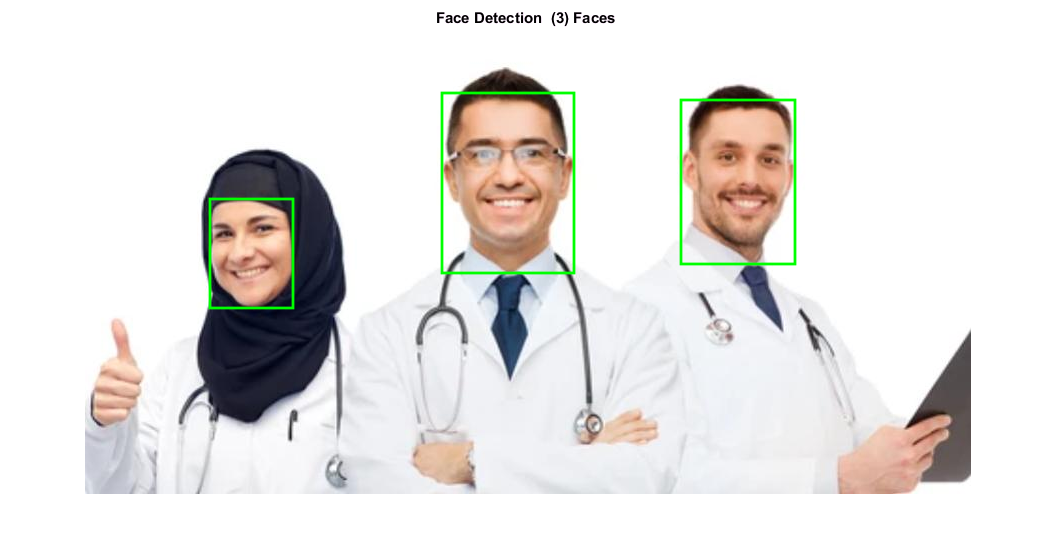

imshow(uint8(I));
title(['Face Detection  (',num2str(num_faces),') Faces '])
hold on
for i=1:size(CurBB,1)
    BB = CurBB(i,:);
    rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','g','LineWidth',2) ;
end